## 6.1


% Planeamento

% 1- Ter alfabeto
    alfabeto_nums = ['a':'z' 'A':'Z' '0':'9']

alfabeto_nums = 'abcdefghijklmnopqrstuvwxyzABCDEFGHIJKLMNOPQRSTUVWXYZ0123456789'

%
% 2- Determinar tamanho da chave
     imin = 4;
     imax = 12;
    % tamanho = randi([imin imax])
%
% 3- gerar 1 chave
   % gerar cada um dos caracteres
   %  rand_idx = randi(length(alfabeto), 1,tamanho);
   %   rand_key = alfabeto(rand_idx);
   %   fprintf(1,"Chave = %s\n",rand_key);

NC = 1e2

NC = 100

randKeys(NC, imin, imax, alfabeto_nums)

ans = 1×100 cell array
    {'4h4NgrH77j8'}    {'EXiA4X7Oc05Q'}    {'UyOkRbrcgZ'}    {'t6cBxVXlEB'}    {'RUrQOkhE7'}    {'KnUpFR3'}    {'Hijp0pYp5vmp'}    {'DvZKI4rUU'}    {'JedGW5i'}    {'DaukXtGkL'}    {'OQUBfo'}    {'jZH9eBg7aWY1'}    {'yqXA'}    {'lqji1JIi0MvF'}    {'eohlozd'}    {'6EEu3wgWyozf'}    {'67Jdo'}    {'YackOTO'}    {'HsUlQlwM'}    {'f5WEBBsFFYX'}    {'xYHv62IMK'}    {'sDo0m'}    {'koBt5A'}    {'48Bgq'}    {'KqLSnhs'}    {'AFfqXb'}    {'TEJoC7HGoEMQ'}    {'w9c24Xg'}    {'uQiSgO'}    {'WS43uRmb'}    {'FD4LM1XJlo'}    {'bEk8SFDdQce'}    {'fYYSjOG8'}    {'XCAZfikyZ'}    {'dyGzOMsAa9k'}    {'xmEv'}    {'5dTqAH6z8sRP'}    {'RPlh9kcI'}    {'PlwC8j1NxlA'}    {'hKoxKpsM'}    {'Z8TvKg'}    {'2YqKbAtklAfL'}    {'RRNcetGO'}    {'YS8GugL'}    {'AfqjrBGC2G6'}    {'7oPrPRepn'}    {'0vWPaLx4aC'}    {'CVtWDck'}    {'DjvLlTp4qV'}    {'rfJQH'}    {'NOQN6mR'}    {'hLBCPV'}    {'Pz0ZpMK'}    {'1qth6ODN'}    {'OHSG9ngg'}    {'zBwV'}    {'V58liRfGG'}    {'EyPTGvjKqcU'}    {'BQwTyQ'}    {'BbuAq

keys = randKeys(NC, imin, imax)

keys = 1×100 cell array
    {'itiNTsJpB'}    {'FrpxvsDMwwg'}    {'pqHX'}    {'xmNNMMfJylfQ'}    {'iIUAK'}    {'XCJbQ'}    {'gBqCuvjnbW'}    {'WiVPEwnNl'}    {'NILH'}    {'uQqQPSA'}    {'XxdTGsZlH'}    {'uhbvjLtRM'}    {'jXnWlteHj'}    {'LsIt'}    {'bVPMQtGDB'}    {'mxlPZb'}    {'ePZdWaJO'}    {'UUGhljcf'}    {'WsvZXJZNr'}    {'mpJBvFNEC'}    {'AeLZsYsUx'}    {'lgqLOKa'}    {'VOctKLlnIyG'}    {'jRNWfj'}    {'zkUf'}    {'COqj'}    {'kAVGfuc'}    {'wZQzUhuW'}    {'LGrWgLHRuMRq'}    {'YCrGsNvz'}    {'YrRMXbsIol'}    {'GEIcsxmLSo'}    {'hRhEtPAzTs'}    {'YcYjIEJs'}    {'QbeYHmugn'}    {'rhsgTe'}    {'ucrMPCJUcpck'}    {'LTEdVPoCZL'}    {'wyDnMAHqhys'}    {'OIgbDpWZoPU'}    {'TXCLDbxHB'}    {'WRStETW'}    {'kIdvIWQzNv'}    {'ZSuxmOTVDFhU'}    {'kUNToJIg'}    {'oLoUQuz'}    {'RFDqxLTLaJ'}    {'wgQqmrt'}    {'DuuAIXLu'}    {'gdeiqpaCehG'}    {'YDZCArwzdUd'}    {'QuFQUWj'}    {'UEAFQB'}    {'xwYGK'}    {'sACiDKwRMs'}    {'uOMwKXOK'}    {'uExc'}    {'RaSeIA'}    {'DgIFc'}    {'hbwR'}    {'BSfVfA

## 6.2

% INPUT: Temos lista de chaves

funcoes = { 'djb2', 'sdbm'}

funcoes = 1×2 cell array
    {'djb2'}    {'sdbm'}



hashcodes= zeros(length(keys),1);
% 1- iterar toda a lista
for i = 1:NC
    for M = [5e5 1e6 2e6]
        for j = 1:2
        % 2- aplicar função de hash a cada chave
            hc = string2hash(keys{i}, funcoes{j});
        
        % 3- Transformar hashcode para intervalo 0: M - 1          M = (5e5, ...
            hc = mod(hc, M);
        
        % 4- guardar hashcodes num a-rray de NUM_CHAVES
            hashcodes(i, j) = hc;
        end
    end
end
hashcodes

hashcodes =      1155181     1786263
     1664111      243300
      624071       54982
      579292      157362
     1392169     1331432
     1005006     1784323
      260125      778661
      402183     1931368
     1358769     1461476
     1816487      436995


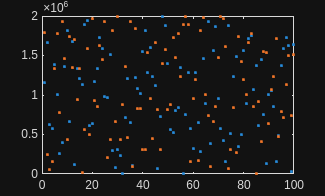

plot(1:NC,hashcodes,'.')

## 6.3

n = 8000;
BF = inicializar(n);
k = 3;

elemento = 'Aveiro';
BF = adicionar(elemento,BF,k)

Aveiro1
Aveiro12
Aveiro123


BF = 1×8000 uint8 row vector
   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0


find(BF == 1)

ans =         3211        6427        6436


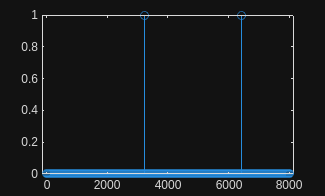

sum(BF);
stem(BF);



x = 'Aveiro'

x = 'Aveiro'

r = pertence(x,BF,k)

Aveiro1
Aveiro12
Aveiro123


r = logical
   1
